# **Procesarea imaginilor digitale**

####     ***Descriere:***

        În prezent, inteligența artificială promite progrese remarcabile, așa cum heliograful lui Niépce a revoluționat captura imaginii în 1839. Deși fotografia digitală a devenit accesibilă, redarea precisă a realității rămâne un obiectiv tehnologic complex. Factori precum rezoluția, claritatea (sharpness), zgomotul de imagine, fidelitatea culorilor, intervalul dinamic și compoziția optică continuă să influențeze semnificativ calitatea imaginii generate de senzorii camerelor foto.

## 1. Flip

    ***Descriere: ***

        Funcția **Flip **inversează orientarea unei imagini, fie pe orizontală, fie pe verticală, prin rearanjarea poziției pixelilor corespunzator direcției specificate.

***    Implementare:***

function new = flipFunction(imag, Direction)
    switch lower(Direction)
        case "horizontal"
            new = imag(1:end, end:-1:1, 1:3);
        case "vertical"
            new = imag(end:-1:1, 1:end, 1:3);
        otherwise
            error("Direction can be 'horizontal' or 'vertical'")
    end
end

***    Exemplu:***

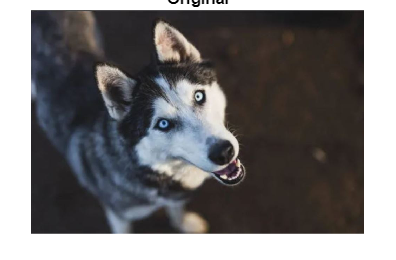

image = imread("Imagini\poza1.JPG");
imshow(image), title("Original");


disp("Flip");

Flip


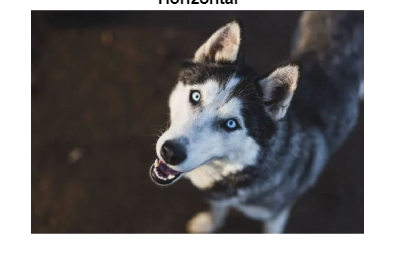

H_flip_image = flipFunction(image, "horizontal");
imshow(H_flip_image), title("Horizontal");

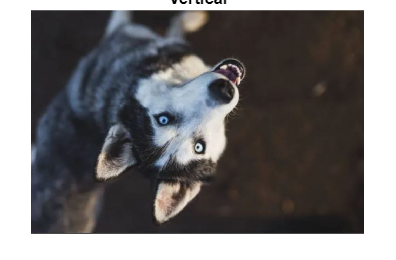


V_flip_image = flipFunction(image, "vertical");
imshow(V_flip_image), title("Vertical");


clear

## 2. Stacking (h/v stack)

    ***Descriere:***

        Funcția **Stacking **combină două imagini prin alăturare, fie pe verticală, fie pe orizontală, rezultând o singură imagine compusă.

***    Implementare:***

function new = Stacking(first_img, second_img, Direction)
    try
        [first_rows, first_cols, ~] = size(first_img);
        [second_rows, second_cols, ~] = size(second_img);
        if Direction == "horizontal"
            height = max(first_rows, second_rows);
            width = first_cols + second_cols;
            new = zeros(height, width, 3, 'like', first_img);
            
            new(1:first_rows, 1:first_cols, :) = first_img;
            new(1:second_rows, first_cols+1:width, :) = second_img;

        elseif Direction == "vertical"
            height = first_rows + second_rows;
            width = max(first_cols, second_cols);
            new = zeros(height, width, 3, 'like', second_img);

            new(1:first_rows, 1:first_cols, :) = first_img;
            new(first_rows+1:height, 1:second_cols, :) = second_img;

        else
            error("Direction can be 'horizontal' or 'vertical'")
        end
    catch Er
        disp("Error: " + Er.message);
    end
end

***    Exemplu:***

first_image = imread("Imagini\poza1.JPG");
second_image = imread("Imagini\poza2.JPG");

imshow(first_image), title("Original");

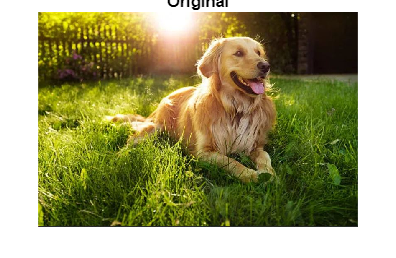

imshow(second_image), title("Original");


disp("Stacked");

Stacked


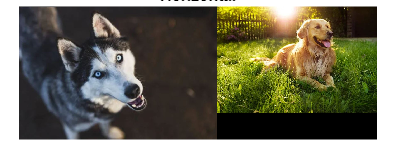

H_stacked_image = Stacking(first_image, second_image, "horizontal");
imshow(H_stacked_image), title("Horizontal");

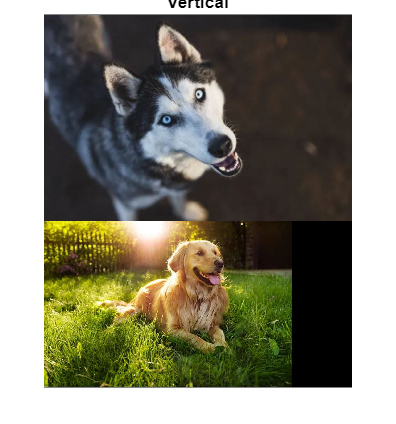


V_stacked_image = Stacking(first_image, second_image, "vertical");
imshow(V_stacked_image), title("Vertical");



clear

## 3. Zoom

    ***Descriere:***

        Funcția **Zoom **mărește o imagine prin replicarea fiecarui pixel într-un bloc de dimensiune proporțională cu un factor dat, rezultând o imagine de dimensiuni mai mari, dar cu acelasi conținut vizual.

***    Implementare:***

function new = Zoom(img, factor)
    try 
        [rows, cols, ~] = size(img);
        new = zeros(rows * factor, cols * factor, 3, 'like', img);

        for i = 1:rows
            for j = 1:cols
                for x = 1:factor
                    for y = 1:factor
                        new((i-1) * factor + x, (j-1) * factor + y, 1:3) = img(i,j,1:3);
                    end
                end
            end
        end
    catch Er
        disp("Error: " + Er.message);
    end
end

***    Exemplu:***

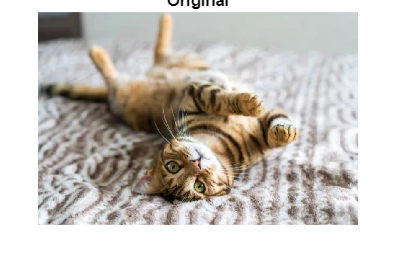

image = imread("Imagini\poza3.JPG");
imshow(image), title("Original");

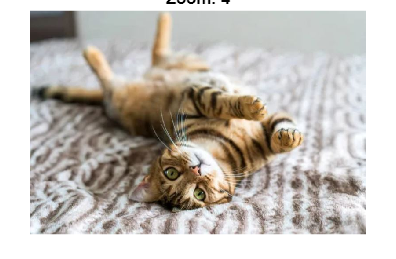


zoom_image = Zoom(image, 4);
imshow(zoom_image, 'InitialMagnification', 100), title("Zoom: 4");


clear

## 4. Crop to shape

    ***Descriere:***

        Funcția **Shape **decupează o imagine conform unei forme geometrice specificate (pătrat sau cerc).

***    Implementare:***

function new = Shape(img, r, shape)
    try
        [rows, cols, ~] = size(img);
        new = zeros(rows, cols, 3, 'like', img);

        Ox = round(rows/2);
        Oy = round(cols/2);

        switch lower(shape)
            case "square"
                new(Ox - r:r + Ox, Oy - r:r + Oy, 1:3) = img(Ox - r:r + Ox, Oy - r:r + Oy, 1:3);
            case "circle"
                for i = 1:rows
                    for j = 1:cols
                        if sqrt((Ox - i)^2 + (Oy - j)^2) <= r
                            new(i,j,1:3) = img(i,j,1:3);
                        end
                    end
                end
            otherwise
                error("The shape does not exist!");
        end
    catch Er
        disp("Error: " + Er.message);
    end
end

***    Exemplu:***

image = imread("Imagini\poza1.JPG");
imshow(image), title("Original");

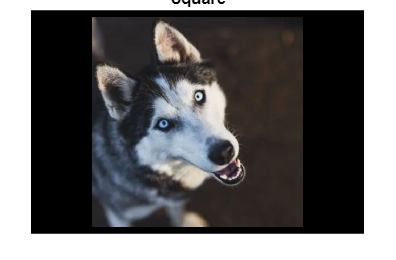


square_image = Shape(image, 300, 'square');
imshow(square_image), title("Square");

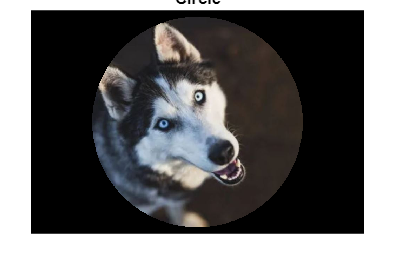


circle_image = Shape(image, 300, 'circle');
imshow(circle_image), title("Circle");


clear

## 5. Modificarea luminozității / contrastului

    ***Descriere:***

        Funcția **Brightness_Contrast **ajustează valorile de intensitate ale pixelilor unei imagini, fie prin adăugarea unei constante, fie prin inmultirea cu un factor.

***    Implementare:***

function new = Brightness_Contrast(img, value_Brightness, value_Contrast)
    new = [];
    try
        if((value_Brightness >= -100) && (value_Brightness <= 100))
            double_image = double(img);
            percentage = (value_Brightness / 100) * 255;
            double_image = double_image + percentage;

            if ~(value_Contrast >= 0 && value_Contrast <= 5)
                error("Contrast value must be between 0 and 5");
            end

            double_image = (double_image - 128) * value_Contrast + 128;
            new = uint8(min(max(double_image,0),255));
        else
            error("Brightness value must be between -100 and 100.");
        end
    catch Er
        disp("Error: " + Er.message);
    end
end

***    Exemplu:***

image = imread("Imagini\poza2.JPG");
imshow(image), title("Original");

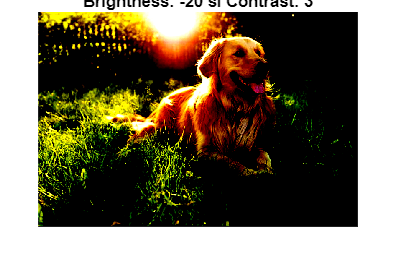


Brightness_Contrast_image = Brightness_Contrast(image, -20, 3);
imshow(Brightness_Contrast_image), title("Brightness: -20 si Contrast: 3");


clear

## 6. Compresia imaginii

    ***Descriere:***

        Funcția **Compression **reduce dimensiunea fișierului prin eliminatrea redundanței sau a detaliilor greu perceptibile, păstrând cât mai mult din calitatea vizuală originală.

***    Implementare:***

function new = Compression(img, percentage)
    new = [];
    try
        if(percentage >= 0 && percentage <= 100)
            double_img = im2double(img);

            R = double_img(:,:,1);
            G = double_img(:,:,2);
            B = double_img(:,:,3);
        
            [U_R, S_R, V_R] = svd(R);
            [U_G, S_G, V_G] = svd(G);
            [U_B, S_B, V_B] = svd(B);
        
            com_R = U_R(:,1:percentage) * S_R(1:percentage, 1:percentage) * V_R(:,1:percentage)';
            com_G = U_G(:,1:percentage) * S_G(1:percentage, 1:percentage) * V_G(:,1:percentage)';
            com_B = U_B(:,1:percentage) * S_B(1:percentage, 1:percentage) * V_B(:,1:percentage)';
            
            new = cat(3, com_R, com_G, com_B);
        else
            error("Percentage value must be between 0 and 100.");
        end
    catch Er
        disp("Error: " + Er.message);
    end
end

***    Exemplu:***

image = imread("Imagini\poza3.JPG");
imshow(image), title("Original");

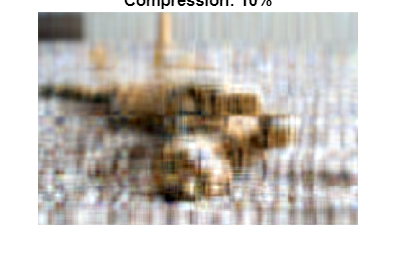


Comp_image = Compression(image,10);
imshow(Comp_image), title("Compression: 10%");


clear

## 7. Estomparea (blur)

    ***Descriere:***

        Funcția **Estompare **aplică un filtru care reduce variațiile bruste de intensitatea dintre pixeli, netezind tranzițiile si diminuarea detaliilor fine pentru a obține un aspect mai uniform sau pentru a reduce zgomotul vizual din imagine.

***    Implementare:***

function new = Estompare(img, value_Blur)
    try
        [rows, cols, channels] = size(img);
        new = zeros(rows,cols, channels, 'like', img);

        if ~(value_Blur >= 1 && value_Blur <= min(rows,cols))
            error("'value_Blur' must be between 0 and " + min(rows,cols) + ".");
        else

            for c = 1:channels
                for i = 1:rows
                    top = max(i - value_Blur, 1);
                    bottom = min(rows, i + value_Blur);
                    for j = 1:cols
                        left = max(j - value_Blur, 1);
                        right = min(cols, j + value_Blur);
    
                        submatrix = img(top:bottom, left:right, c);
                        new(i,j,c) = sum(submatrix(:)) / numel(submatrix);
                    end
                end
            end

        end

    catch Er
        disp("Error: " + Er.message);
        new = img;
    end
end

***    Exemplu:***

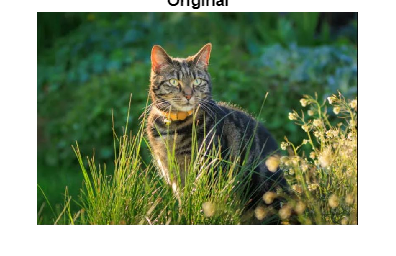

image = imread("Imagini\poza4.JPG");
imshow(image), title("Original");

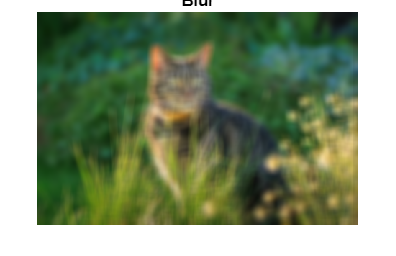


Blur_image = Estompare(image, 10);
imshow(Blur_image), title("Blur");


clear

## 8. Detectarea conturului

    ***Descriere:***

***    Implementare:***

%

***    Exemplu:***

%